# Compare modes of different (but similar) surfaces

Each surface will be comprised of the same number of vertices and faces, and each face is an equilaterial triangle. 

%%% User inputs
lump = false; 
nDouble = 2; 
nModes = 25; 

## Choose one of the following cells

[v1,f1] = equilateralMesh(4); 
[v1,f1] = increasePatch(v1, f1); 
for ii = 1:nDouble; [v1,f1] = increasePatch(v1,f1); end

[v2, f2] = equilateralMesh(16); 
v2 = v2/2; % normalise surface area
for ii = 1:nDouble; [v2,f2] = increasePatch(v2,f2); end

[v1,f1] = equilateralMesh(10); 
[v1,f1] = augmentFace(v1, f1, 1:5); 
for ii = 1:nDouble; [v1,f1] = increasePatch(v1,f1); end

[v2, f2] = equilateralMesh(20); 
for ii = 1:nDouble; [v2,f2] = increasePatch(v2,f2); end

[v1,f1] = equilateralMesh(6); 
[v1,f1] = augmentFace(v1, f1, 1);
for ii = 1:nDouble; [v1,f1] = increasePatch(v1,f1); end

[v2, f2] = equilateralMesh(8); 
for ii = 1:nDouble; [v2,f2] = increasePatch(v2,f2); end

## Calculate and visualise results

s1 = calc_geometric_eigenmode(struct('vertices', v1, 'faces', f1), nModes, [], lump); 
s2 = calc_geometric_eigenmode(struct('vertices', v2, 'faces', f2), nModes, [], lump); 

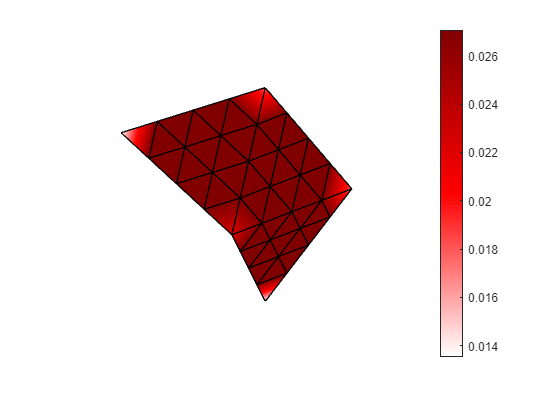

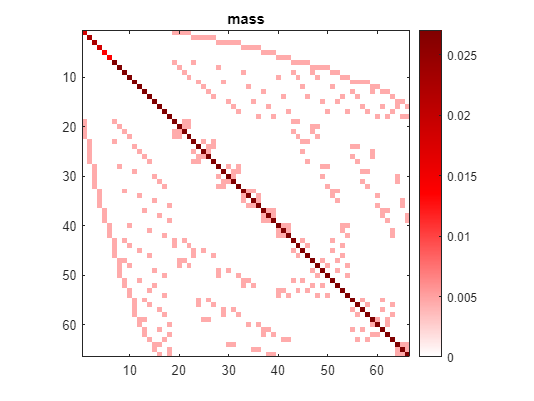

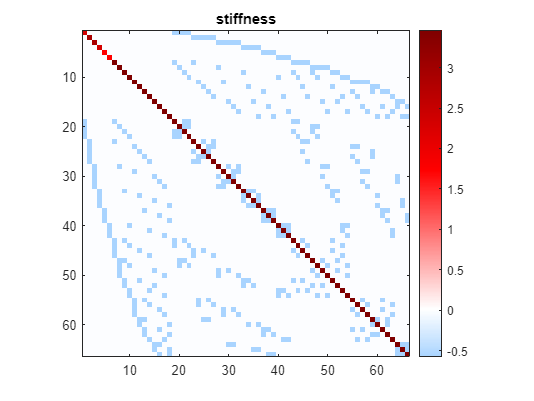

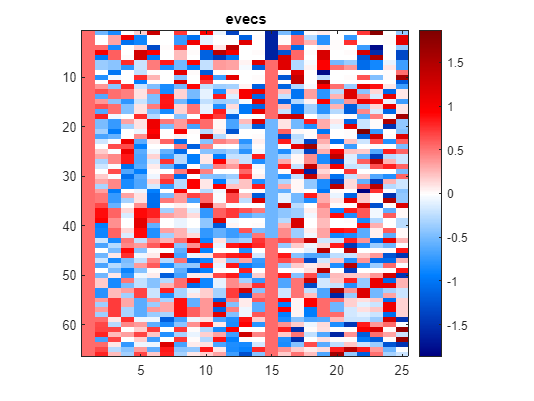

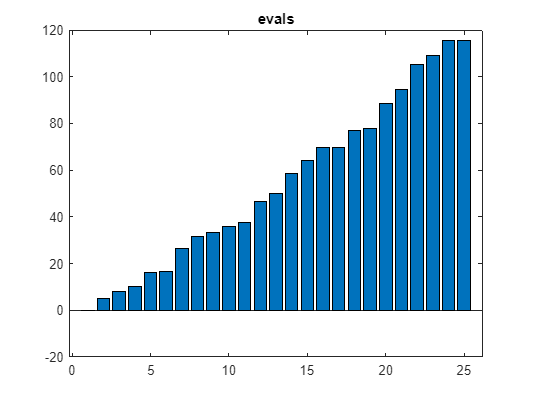

drawFigs(s1);

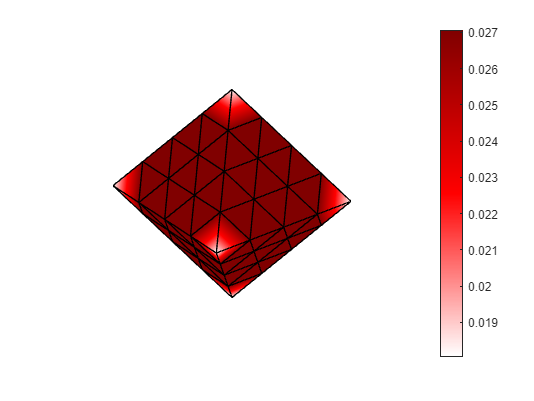

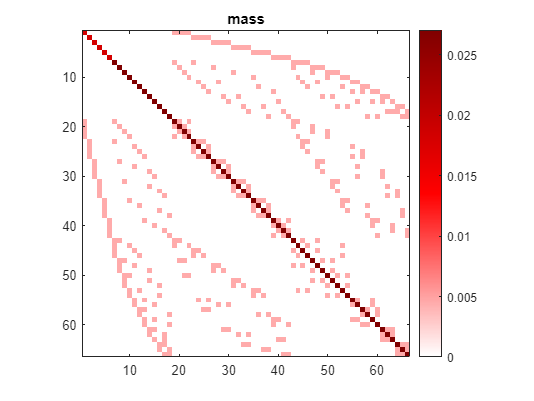

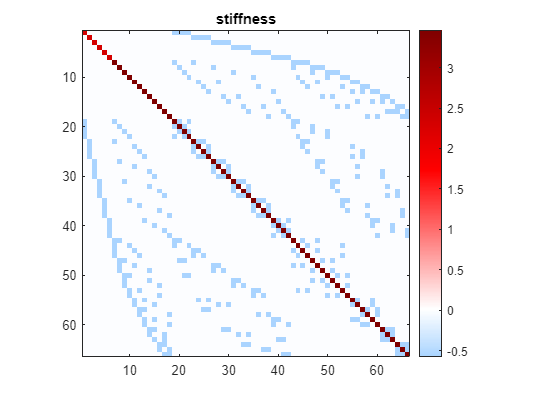

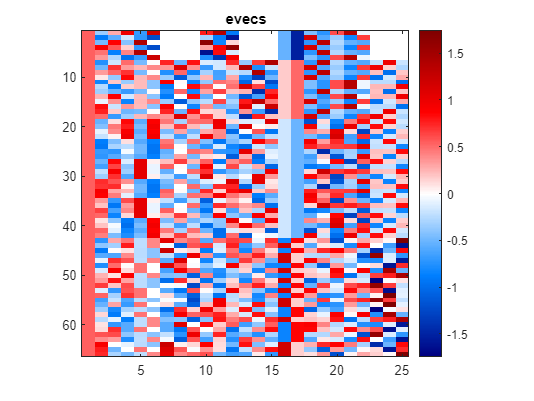

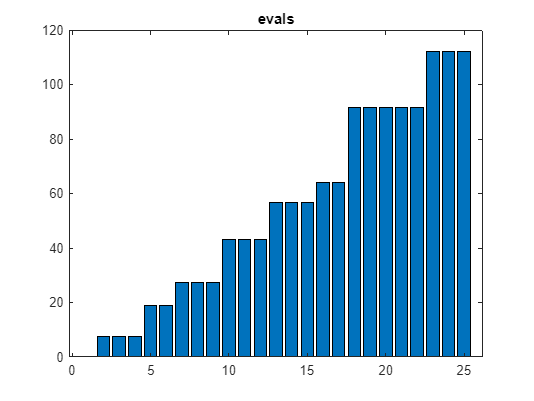

drawFigs(s2);

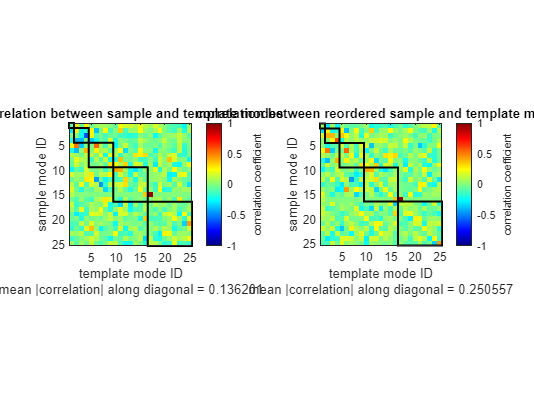

matchModes(s1.evecs, s2.evecs, 'showFigure', 1);

## Helpers

function drawFigs(s)

figure; 
patchvfc(s.vertices, s.faces, full(diag(s.mass)), 'EdgeColor', 'k'); 
axis equal tight off; view(3); 
colormap(bluewhitered_mg); colorbar; 

figure; 
imagescmg(s.mass); 
colormap(bluewhitered_mg);
title('mass'); 

figure; 
imagescmg(s.stiffness); 
colormap(bluewhitered_mg);
title('stiffness'); 

figure; 
imagescmg(s.evecs); 
colormap(bluewhitered_mg);
title('evecs'); 

figure; 
bar(s.evals); 
title('evals'); 

end